## Section 1: Taylor & Maclauren Polynomial Review

Say we have an unknown function $f\left(x\right)$ that we want to approximate at $x=0$ with the function $p\left(x\right)$.

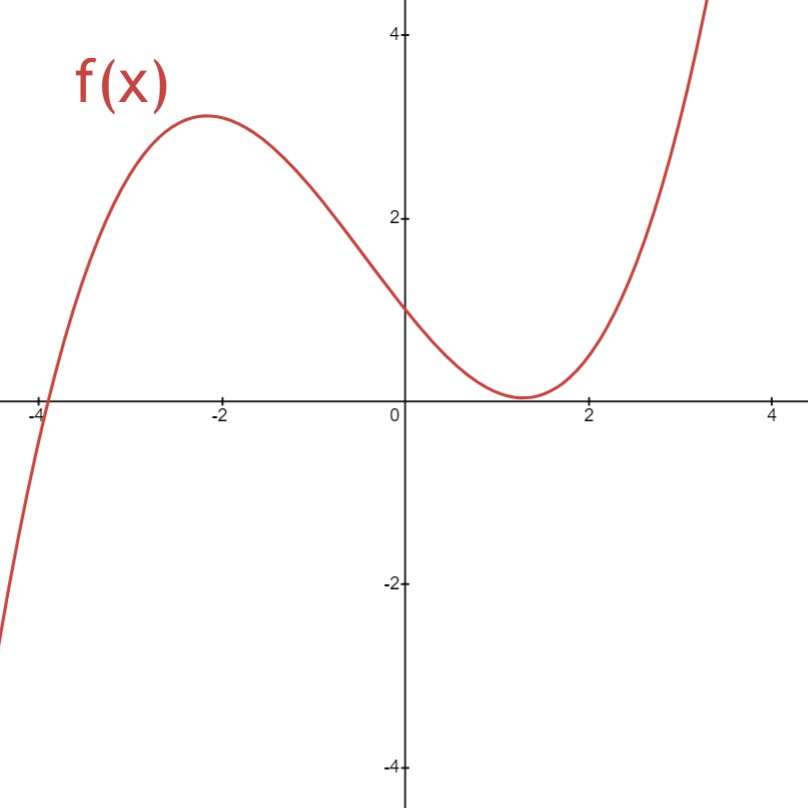

The simplist way to do this is to set $p\left(x\right)=f\left(0\right)$. In this example we can visually see that $f\left(0\right)=1$ thus $p\left(x\right)=1$ 

Plotted out it would look like this

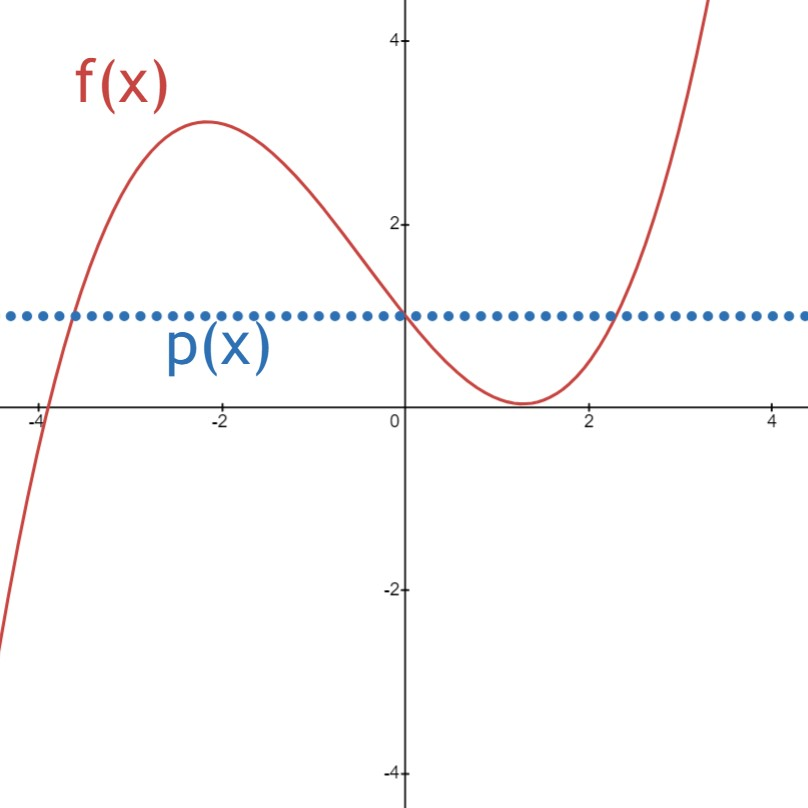

The approximation $p\left(x\right)$ is really acurate when $x=0$ but not so accurate at other points. One way we could 

try to improve the approximation is to make the derivative of $p\left(x\right)$ equal to the derivative of $f\left(x\right)$ at $x=0$.

Written out formally we want: $p^{\prime } \left(0\right)=f^{\prime } \left(0\right)$

We can visually try to estimate the derivative of $f$ but for this example it will be given as $f^{\prime } \left(0\right)=-1\ldotp 25$

We can set $p^{\prime } \left(x\right)$ by adding a term to our $p$ function: 


$$p\left(x\right)=f\left(0\right)+f^{\prime } \left(0\right)\cdot x\;\;\;\to \;\;p\left(x\right)=1-1\ldotp 25x$$
 

Adding this term doesn't change how $p\left(x\right)$ evaluates at $x=0$ because the new term is multiplied by $x$.

i.e. solving $p\left(0\right)=f\left(0\right)+f^{\prime } \left(0\right)\cdot 0=f\left(0\right)\;\;\;\;\textrm{or}\;\;\;\;p\left(0\right)=1-1\ldotp 25\cdot 0=1$

We can also see that the derivative of our new $p\left(x\right)$ solves so that we are only left with $f^{\prime } \left(0\right)$:


$$p^{\prime } \left(0\right)=0+f^{\prime } \left(0\right)\cdot 1=f^{\prime } \left(0\right)$$


Plotted out it looks like this:

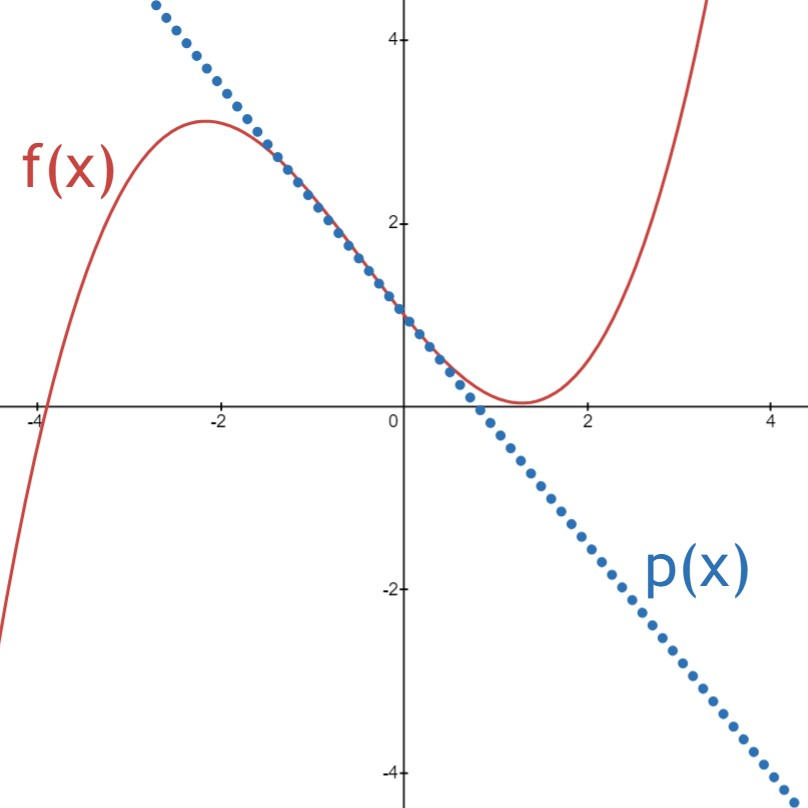

Repeating this process we can try and set the second derivative to be the same: $p^{\prime \prime } \left(0\right)=f^{\prime \prime } \left(0\right)$ with:


$$p\left(x\right)\;=f\left(0\right)+f^{\prime } \left(0\right)\cdot x+f^{\prime \prime } \left(0\right)\cdot {\frac{1}{2}\cdot x}^2$$


While not explicitly computed here, the results of doing this result in the following graph for $p\left(x\right)$:

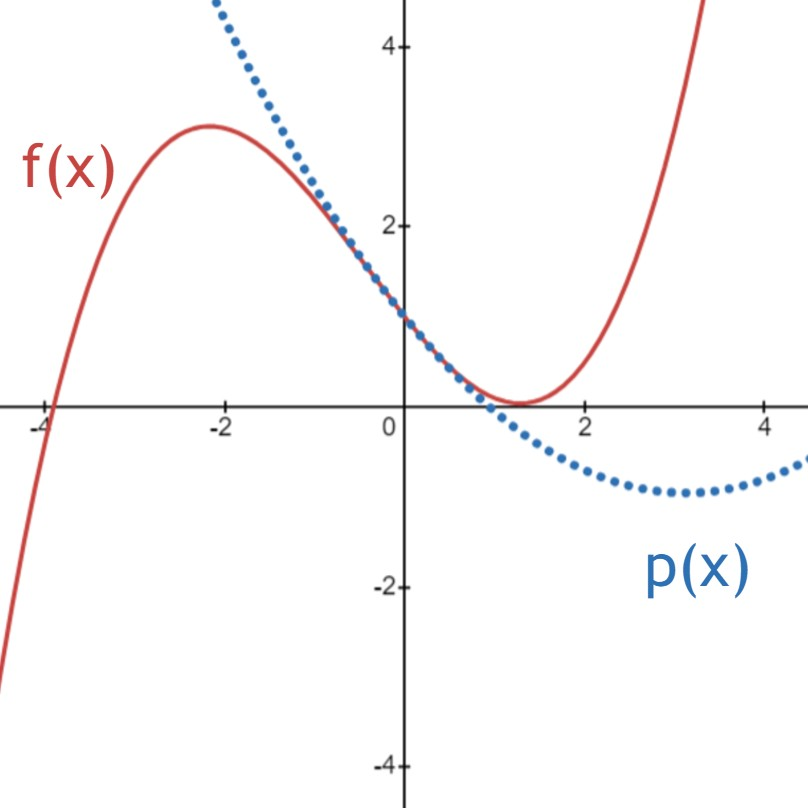

In general, differentiable function $f\left(x\right)$ can be approximated at $x=0$ using $n$ terms as follows:


$$p\left(x\right)=f\left(0\right)+f^{\prime } \left(0\right)x+\frac{f^{\prime \prime } \left(0\right)}{2!}x^2 +\frac{f^{\prime \prime \prime } \left(0\right)}{3!}x^3 +\ldots\frac{f^{\left(n\right)} \left(0\right)}{n!}x^n$$


This can be written in summation notation as:


$$p\left(x\right)=\sum_{n=0} \frac{f^{\left(n\right)} \left(0\right)}{n!}\cdot x^n$$


This is the definition of the Maclaurin polynomial.

#### Exercise 1: Write a Matlab function that can approximate a symbolic function with n terms at the point $x=0$

clear; % Clear old variables (helps with stability)

% A framework for your function is given
function approximate = maclaurin(fun, n)
    % INPUT:
    %      fun: a symbolic function to approximate
    %      n: the order to approximate the function to (starting at 0)
    % OUTPUT
    %      approximate: a symbolic approximation of fun using n+1 terms
    syms x 
    
    %%%%%%%%%%%%%
    %YOUR CODE HERE%
    %%%%%%%%%%%%%

    %ANSWER KEY (DELETE)%
    approximate = 0;
    for i = 0:n
        approximate = approximate + subs(diff(fun,i),0)/factorial(i) * x^i;
    end
    %%%%%%%%%%%%%%%%

end

% Here is a test case for your function (DO NOT CHANGE)
syms x
f = 5*x^3 - 6*x^2 + 3*x - 4;

% You can experiment with different n values here
n = 1; % Values greater than 3 should not return new answers
maclaurin(f,n)

% Run Tests on your function (DO NOT CHANGE)
assert(maclaurin(f,0) == -4, ' should return -4 i.e. f(0)')
assert(maclaurin(f,1) == 3*x-4, 'This should return 3x-4')
assert(maclaurin(f,2) == -6*x^2+3*x-4,'This should return -6x^2 + 3x - 4')
assert(maclaurin(f,3) == 5*x^3-6*x^2+3*x-4, 'This should return 5x^3 - 6x^2 + 3x - 4')
disp('All Tests Passed!');

This would be much more useful if the function could be estimated at a point other then $x=0$. Fortunately, 

it can be with a simple modification to the formula! The formula for finding a polynomial estimation of a function

at a point $c$ is as follows:


$$p\left(x\right)=f\left(c\right)+f^{\prime } \left(c\right)\left(x-c\right)+\frac{f^{\prime \prime } \left(c\right)}{2!}{\left(x-c\right)}^2 +\frac{f^{\prime \prime \prime } \left(c\right)}{3!}{\left(x-c\right)}^3 +\ldots\frac{f^{\left(n\right)} \left(c\right)}{n!}{\left(x-c\right)}^n$$


or


$$p\left(x\right)=\sum_{n=0} \frac{f^{\left(n\right)} \left(c\right)}{n!}\cdot {\left(x-c\right)}^n$$


#### Exercise 2: Write a Matlab function that can approximate a symbolic function with n terms at an arbitrary point c

clear; % Clear old variables (helps with stability)

% A framework for your function is given
function approximate = taylor(fun, n, c)
    % INPUT:
    %      fun: a symbolic function to approximate
    %      n: the order to approximate the function to (starting at 0)
    %      c: the point at which to approximate fun
    % OUTPUT
    %      approximate: a symbolic approximation of fun at c using n+1 terms
    syms x 
    
    %%%%%%%%%%%%%
    %YOUR CODE HERE%
    %%%%%%%%%%%%%

    %ANSWER KEY (DELETE)%
    approximate = 0;
    for i = 0:n
        approximate = approximate + subs(diff(fun,i),c)/factorial(i) * (x-c)^i;
    end
    %%%%%%%%%%%%%%%%

end

% Here is a test case for your function (DO NOT CHANGE)
syms x
f = 0.1*x^4 + 0.5*x^3 - 3*x - 2;

% You can experiment with different n and c values here
n = 0;
c = 2;
taylor(f,n,c)

% Run Tests on your function (DO NOT CHANGE)
assert(taylor(f,0,0) == -2, ' should return 2')
assert(taylor(f,0,2) == -12/5, 'This should return -12/5 or -2.4')
assert(simplify(taylor(f,1,1)) == -11/10*x-33/10, 'This should return -11x/10 - 33/10')
assert(simplify(taylor(f,2,-2)) == (-3/5)*x^2-(13/5)*x-(6/5),'This should return (-3/5)*x^2 - (13/5)*x - (6/5)')
disp('All Tests Passed!');